# Network Intrusion Detector

clear;
clc;

a) load dataset

dataset2 = load("cw_dataset_2class.txt");


% dataset2 = normalize(dataset2)

% shuffle data
selectRows = size(dataset2,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset2(shuffle, :);

% transpose
shuffledDataset = shuffledDataset';
% [trainingDataset, validationDataset, testingDataset] = dividerand(dataset2, 2/3, 0, 1/3);
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);
% trainingDataset = trainingDataset';
% validationDataset = validationDataset';
% testingDataset = testingDataset';

b) Create training data, training target, testing data and testing target. 

%get preprocessing data from columns 1-41 
trainingData = trainingDataset(1:41,:);
% get target data from columns 42
trainingTargetData = trainingDataset(42,:);

% get preprocessing data from columns 1-41 
testingData = testingDataset(1:41,:);
% get target data from columns 42 
testingTarget = testingDataset(42,:);


c) Select Pattern Recognition Neural Network (patternnet)

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

d) Define the number of neurons of the neural network (assume only one hidden layer), define the neural network parameters, e.g. epochs, error goal, and learning rate.

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Update parameters
net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

e) Train the neural network based on the training dataset created, and view the trained net (similar as Figure 5, input and output numbers are just for illustration).

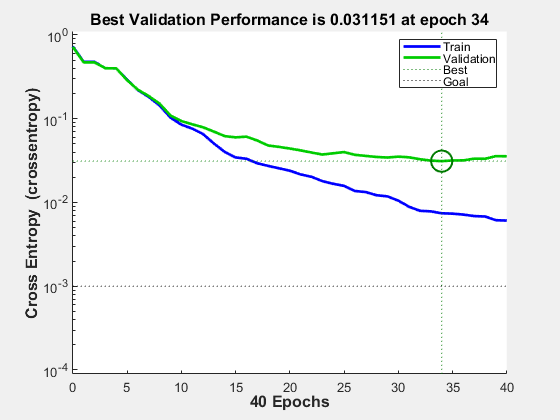

% train dataset 
[net, tr] = train(net, trainingData, trainingTargetData);
view(net)
plotperform(tr);%plot performance graph

f) Test the trained net using testing dataset and evaluate its performance (e.g. classifier accuracy and recall rate). You may run several times for training and testing to get an average performance value. Why does each run has different results?

% array of results
% cross etropy
cEntropys = [];
% Accuracy
accuracies = [];
% Recall Rate
recallRates = [];
% precision
precisions = [];

% run 10 times to gather 10 results for each performance metric 
for it = 1:10
    % Define the number of neurons
    numOfNeurons = 10;
    %select pattern net
    net = patternnet(numOfNeurons);
    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;
    % train dataset 
    [net] = train(net, trainingData, trainingTargetData);

    % run neural network on testing data
    predictedData = net(testingData);
    % get performance of the neural network on the testing data
    perp = perform(net, testingTarget, predictedData);
    % display performance value (cross entropy)
%     disp("Cross etropy:" + perp)
    % add cross entropy value to array of cross entropies
    cEntropys(end+1) = perp;
    
    %round predicted array
    predictedRounded = round(predictedData);
    
    % Accuracy
    numCorrectProdictions = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % compare target against predicted
        if(testingTarget(i) == predictedRounded(i))
            % count correct prediction
            numCorrectProdictions = numCorrectProdictions + 1;
        end
    end
    
    %calculate accuracy 
    accuracy = numCorrectProdictions/ size(predictedRounded,2) * 100;
%     disp("Accuracy: " + accuracy + "%")
    % add accuracy value to array of accuracies
    accuracies(end + 1) = accuracy;

    % recall rate
    totalTruePositive = 0;
    totalActualPositive = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count number of true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if actual positive
        if(testingTarget(i) == 1)
            % count number of actual positives
            totalActualPositive = totalActualPositive + 1;
        end
    end
    % calculate Recall rate
    recallRate = totalTruePositive / totalActualPositive * 100;
%     disp("Recall Rate: " + recallRate + "%")
    % add Recall rate to array of recall rates
    recallRates(end + 1) = recallRate;
    
    % Precision 
    totalTruePositive = 0;
    totalPredictedPositives = 0;
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if predicted positive
        if(predictedRounded(i) == 1)
            % count predicted positives
            totalPredictedPositives = totalPredictedPositives + 1;
        end
    end
    %calculate Precision
    precision = totalTruePositive/totalPredictedPositives * 100;
%     disp("Precision: " + precision + "%")
    % add precision to array of precisions
    precisions(end + 1) = precision;

end

cEntropys

cEntropys =     0.0188    0.0157    0.0388    0.0135    0.0207    0.0111    0.0287    0.0193    0.0176    0.0440


accuracies

accuracies =    99.4444   99.6667   98.5556   99.7778   99.4444   99.7778   99.1111   99.5556   99.6667   98.2222


recallRates

recallRates =    98.9390   99.7347   98.9390   99.7347   98.9390   99.7347   98.6737   99.2042   99.7347   98.6737


precisions

precisions =    99.7326   99.4709   97.6440   99.7347   99.7326   99.7347   99.2000   99.7333   99.4709   97.1279


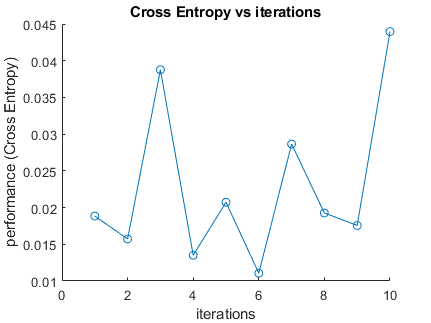


% plot performance metrics 
% cross entropy
figure
hold on
xlabel('iterations')
ylabel('performance (Cross Entropy)')
plot(cEntropys,"o-")
title('Cross Entropy vs iterations')
hold off

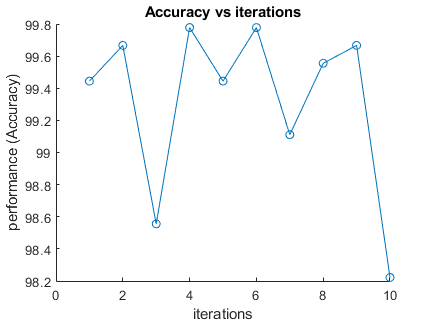

% accuracy
figure
hold on
xlabel('iterations')
ylabel('performance (Accuracy)')
plot(accuracies,"o-")
title('Accuracy vs iterations')
hold off

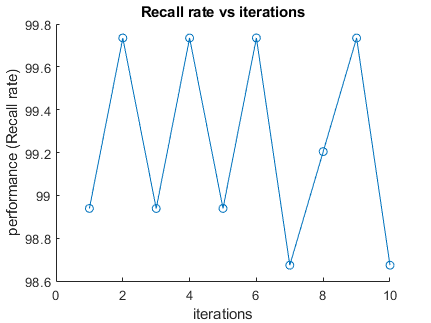

% Recall rate
figure
hold on
xlabel('iterations')
ylabel('performance (Recall rate)')
plot(recallRates,"o-")
title('Recall rate vs iterations')
hold off

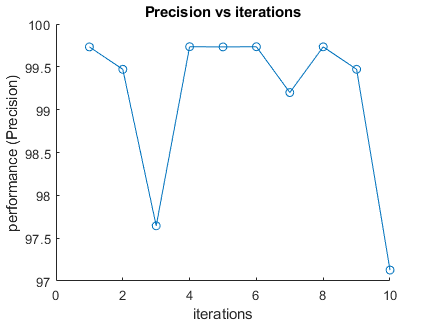

% Precision
figure
hold on
xlabel('iterations')
ylabel('performance (Precision)')
plot(precisions,"o-")
title('Precision vs iterations')
hold off


% average cross entropy
aveCEntropys = sum(cEntropys)/size(cEntropys,2);
disp("Average Cross Entropy: " + aveCEntropys)

Average Cross Entropy: 0.022809


% average Accuracy
aveAccuracy = sum(accuracies)/size(accuracies,2);
disp("Average Accuracy: " + aveAccuracy + "%")

Average Accuracy: 99.3222%


% average Recall rate
aveRecallRate = sum(recallRates)/size(recallRates,2);
disp("Average Recall rate: " + aveRecallRate + "%")

Average Recall rate: 99.2308%


% average Precision
avePrecision = sum(precisions)/size(precisions,2);
disp("Average Precision: " + avePrecision + "%")

Average Precision: 99.1582%


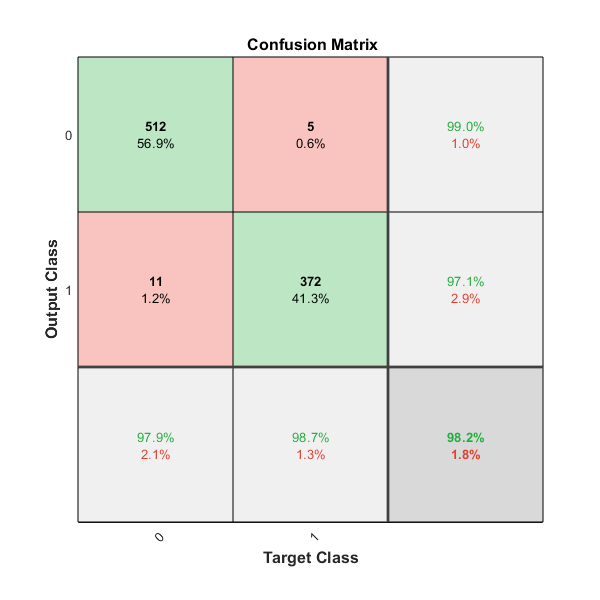



%confusion matrix%%%%%%%%%%%%%%
%[c,cm,ind,per]= confusion(testingTarget, predictedData)
plotconfusion(testingTarget,predictedData)

g) Explore how neural network parameters (e.g. learning rate) and the number of neurons affect the performance of classifier. Explain what are normal stopping criteria for training.

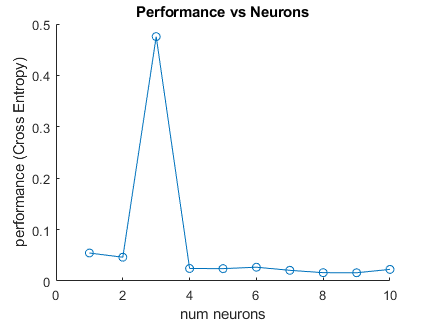

neuronPerformances=[];
for numOfNeurons = 1:10
    %select pattern net
    net = patternnet(numOfNeurons);
    
    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;

    % train network
    [net] = train(net, trainingData, trainingTargetData);
    
    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to neuron performance array
    neuronPerformances(end + 1) = perf;
end
% reset number of neurons to 10
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epochs and error goal
net.trainParam.epochs = 50;
net.trainParam.goal = 0.001;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

%change learning rate 
learningRatePerformance = [];
% learningRates = [1,0.5,0.1,0.05,0.01,0.005,0.001,0.0005,0.0001, 0.00005];
learningRates = [1,0.75,0.5,0.25,0.1,0.075,0.05,0.025,0.01,0.0075];
for it = 1:10
    
    % Define learning rate
    net.trainParam.lr = learningRates(it);

    %train network
    [net] = train(net, trainingData, trainingTargetData);

    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to learning rate performance array
    learningRatePerformance(end + 1) = perf;
end
% learningRatePerformance
% learningRates

% plot perfromance (Cross entropy) graphs
figure
hold on
xlabel('num neurons')
ylabel('performance (Cross Entropy)')
plot(neuronPerformances,"o-")
title('Performance vs Neurons')
hold off

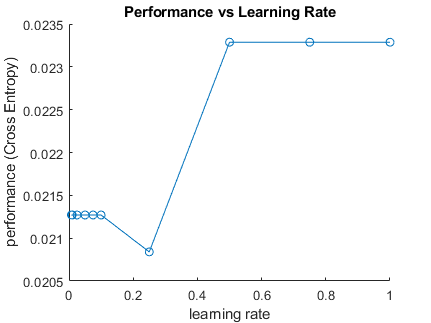


figure
hold on
xlabel('learning rate')
ylabel('performance (Cross Entropy)')
plot(learningRates,learningRatePerformance,"o-")
title('Performance vs Learning Rate')
hold off

h) After completion of intrusion detector for just two classes (‘normal’ and ‘attack’), you now decide to further develop intrusion detection classifier for 3 classes (i.e. ‘normal’, DoS and probing attack), and 5 classes (i.e. ‘normal’, ‘smurf’, ‘neptune, ‘satan’ and ‘ipsweep’). What performance can you get for the intrusion detection classifier?

% 3 classes
dataset3 = load("cw_dataset_3class.txt");

% shuffle data
selectRows = size(dataset3,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset3(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:44,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:44,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp(perp);

    0.0019



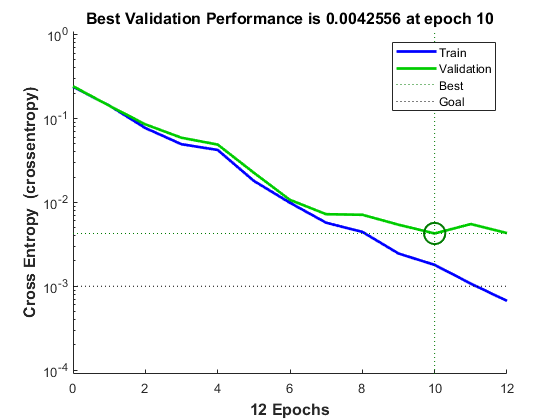

plotperform(tr);%plot performance graph

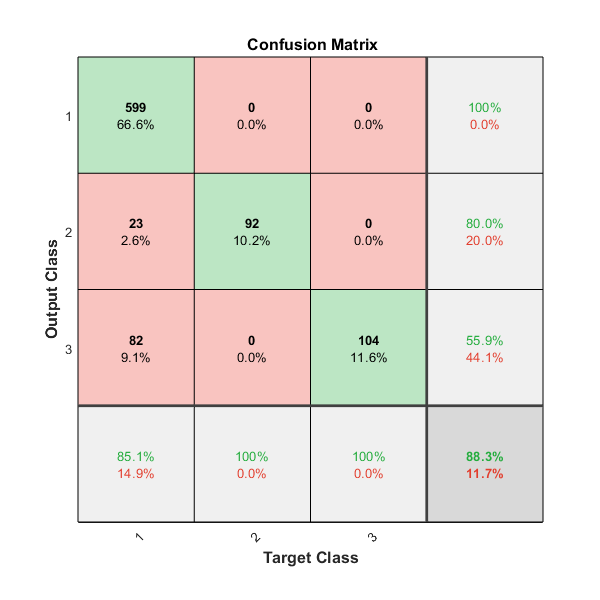

plotconfusion(testingTarget,predictedData)


% 5 classes
dataset5 = load("cw_dataset_5class.txt");

% shuffle data
selectRows = size(dataset5,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset5(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:46,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:46,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp(perp);

    0.0018



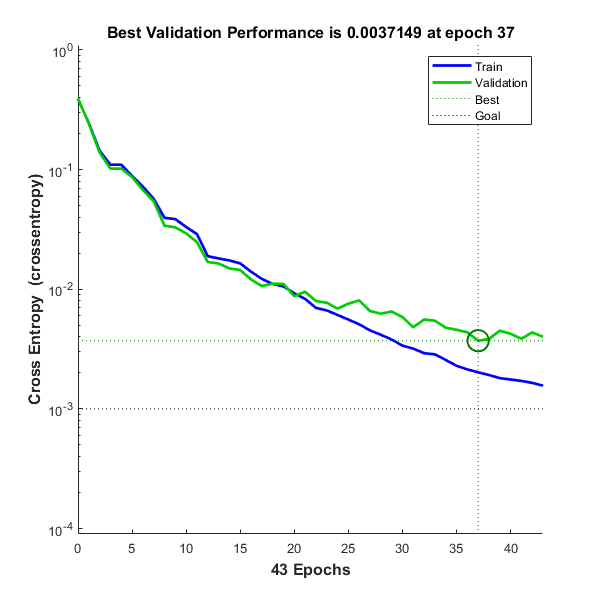

plotperform(tr);%plot performance graph

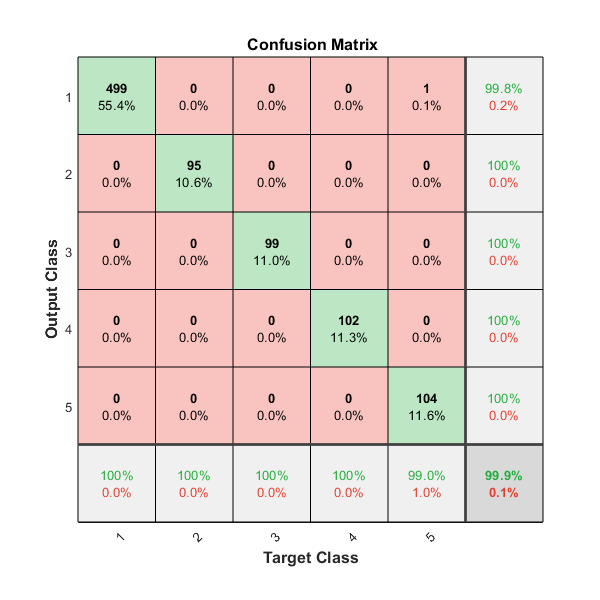


plotconfusion(testingTarget,predictedData)